Storage =dir(fullfile("C:","Users","Rohan Mahesh Rao","Desktop","DIP_project","Testset","speckled","*.png"));
fprintf("No.of images in the speckled set: %d\n",numel(Storage));

No.of images in the speckled set: 348



Noisy_set  = "C:\Users\Rohan Mahesh Rao\Desktop\DIP_project\Noisy_Dataset\";
Clean_set =  "C:\Users\Rohan Mahesh Rao\Desktop\DIP_project\Dataset\";
Testset_noisy = "C:\Users\Rohan Mahesh Rao\Desktop\DIP_project\Testset\speckled";
Testset_clean = "C:\Users\Rohan Mahesh Rao\Desktop\DIP_project\Testset\cleaned";

input = imread("C:\Users\Rohan Mahesh Rao\Desktop\DIP_project\Testset\speckled\speckled291.png");
input_lee = im2double(input);

I_hsv = rgb2hsv(input);
hueval = 10*mean(mean(I_hsv(:,:,1))); 
satval = 10*mean(mean(I_hsv(:,:,2)));
valval = 10*mean(mean(I_hsv(:,:,3))); % extracting hsv features of the image for it to act as a unique image signature

hueval = round(hueval,1);
satval = round(satval,1);
valval = round(valval,1);

hueval = uint8(hueval);
satval = uint8(satval);
valval = uint8(valval);

% file_to_read = fopen('speckled_vals.txt','r');
% A = fscanf(file_to_read,formatSpec);
% B = readtable('speckled_vals.txt','ReadVariableNames',true);
% B.Properties.VariableNames = {'Hue','Sat','Val'}; %This step writes all the hsv values in a text file 

% hue_val = (B(1,"Hue"));
% sat_val = (B(1,"Sat"));
% val_val = (B(1,"Val"));

% hue_val = table2array(hue_val);
% sat_val = table2array(sat_val);
% val_val = table2array(val_val);

formatSpec = '%d';
hsv_inputs = fopen("hsv_inputs.txt",'w');
fprintf(hsv_inputs,formatSpec,hueval,satval,valval); % writing hsv inputs to a buffer file 
disp("HSV values written...");

HSV values written...


pred_file = fopen('predicted_kernel.txt','r');
kernel_val_predicted = uint8(fscanf(pred_file,"%d"));
kernel_val_predicted = double(kernel_val_predicted)

kernel_val_predicted = 5

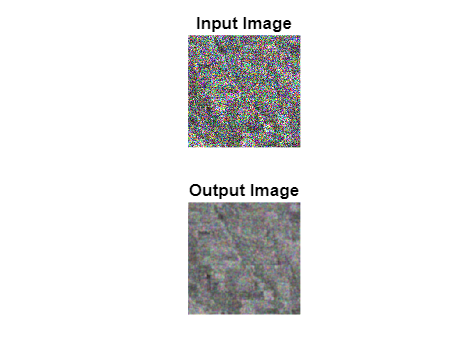

output_img = Leefilter(input_lee,kernel_val_predicted); % despeckling using the predicted kernel value
figure;
subplot(2,1,1);
imshow(input);
title("Input Image");
subplot(2,1,2);
imshow(output_img);
title("Output Image");

CleanLocation = fullfile(Testset_clean,sprintf('cleaned291.png'));
imwrite(output_img,CleanLocation);


function lee_output = Leefilter(img,window_size)

img = double(img);
lee_output = img;
means = imfilter(img, fspecial('average', window_size), 'replicate');
sigmas = sqrt((img-means).^2/window_size^2);
sigmas = imfilter(sigmas, fspecial('average', window_size), 'replicate');

ENLs = (means./sigmas).^2;
sx2s = ((ENLs.*(sigmas).^2) - means.^2)./(ENLs + 1);
fbar = means + (sx2s.*(img-means)./(sx2s + (means.^2 ./ENLs)));
lee_output(means~=0) = fbar(means~=0);

end









